clear; close all; clc;

# Random variables and random processes

## 1.Random Variables

### 1.1. Rolling a fair 6-faced dice (Discrete Var.) 

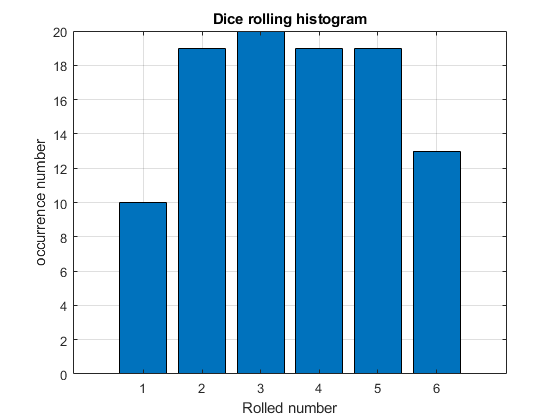

N_faces = 6; %Number of faces in the dice
N_trials = 100; %Number of trials (how many times the dice is rolled)
trials = randi(N_faces,1,N_trials); % Getting random integers 1...6
x_histogram_centers = 1:6; %x-axis for the bin center coordinates
% x-axis for the bin edge coordinates (last edge is for the right edge)
histogram_edges = 0.5:1:6.5;
% Below the ~ sign means that we discard that specific output argument
[hist_count, ~]= histcounts(trials,histogram_edges);
figure
bar(x_histogram_centers,hist_count)
xlabel('Rolled number')
ylabel('occurrence number')
grid on % Set a grid in the plotted figure
title('Dice rolling histogram')

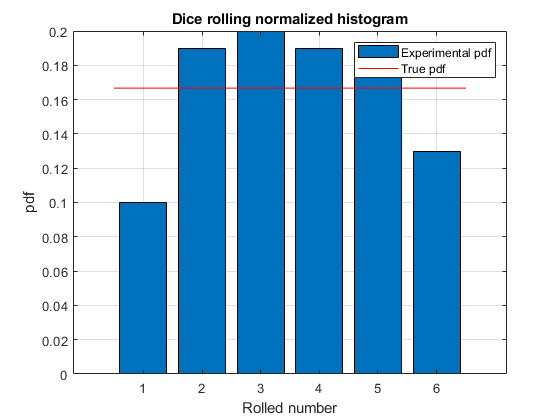

% Histograms can plotted directly as "h = histogram(trials,'BinLimits',[0.5
% 6.5],'BinMethod','integers')", where h is the histogram object.
pdf_experimental = hist_count / N_trials;
figure
bar(x_histogram_centers,pdf_experimental)
xlabel('Rolled number')
ylabel('pdf')
grid on
title('Dice rolling normalized histogram')

one_face_probability = 1/N_faces; % probability of one face of the dice
hold on % avoids removing the previous plot
% plotting true pdf (a line between two points)
plot([0.5 6.5],[one_face_probability one_face_probability],'r')
hold off
% Using legend we can name different data curves in the plot (in order of
% appearance)
legend('Experimental pdf','True pdf')

### 1.2. Normal/Gausian distributed random var. 

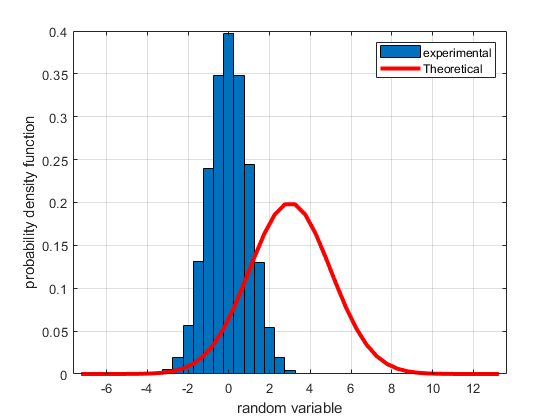

N_samples = 100000; 
X=randn(N_samples, 1);
mu = 3; 
sigma = sqrt(4); % the variance is 4 (i.e. sigma^2=4)
bin_width = 0.5; %bin width (in the x-axis)
bin_centers = -7:bin_width:13; %x-axis for the bin center coordinates 

% x-axis for the bin edge coordinates (last edge is for the right edge): 
bin_edges = (bin_centers(1)-... 
bin_width/2):bin_width:(bin_centers(end)+bin_width/2); % it extend the tail and end of x axis for 0.25 
 
% ~ means that we discard that output argument 
[hist_count, ~]= histcounts(X,bin_edges);  
 
pdf_experimental = hist_count/sum(hist_count*bin_width); 
 
figure 
bar(bin_centers,pdf_experimental,1) 
pdf_true = 1/(sqrt(2*pi)*sigma)*exp(-(mu-bin_edges).^2/(2*sigma^2)); 
hold on 
plot(bin_edges,pdf_true,'r','LineWidth',3) % defines a specific line width 
grid on
legend('experimental', ...
    'Theoretical')
xlabel('random variable')
ylabel('probability density function')


b = 6; 
indices_with_bin_center_larger_than_b = bin_centers > b; 
considered_bin_values = 6.8;
pdf_experimental(indices_with_bin_center_larger_than_b); 
 
%area of the considered bins 
probability_X_larger_than_b = sum(pdf_experimental)...
    /sum(considered_bin_values*bin_width);
analytic_probability = qfunc((b-mu)/sigma);


## 2. Random Process

### 2.1. White noise vs colored noise

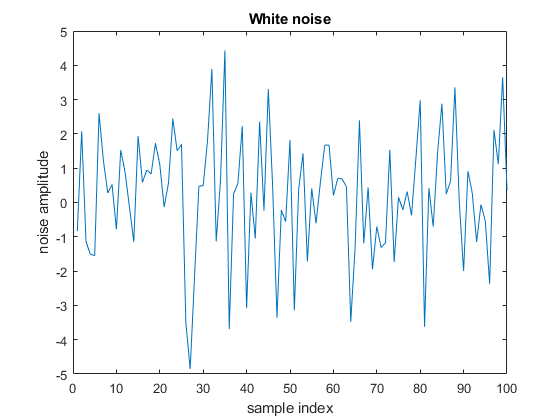

N = 10000; % Number of generated samples 
noise_var = 3; % Desired noise variance 
noise = sqrt(noise_var)*randn(1,N); % Noise signal generation
figure 
plot(noise) 
grid on
xlabel('sample index') 
ylabel('noise amplitude') 
title('White noise') 
xlim([0 100]) %define the x-axis limits 

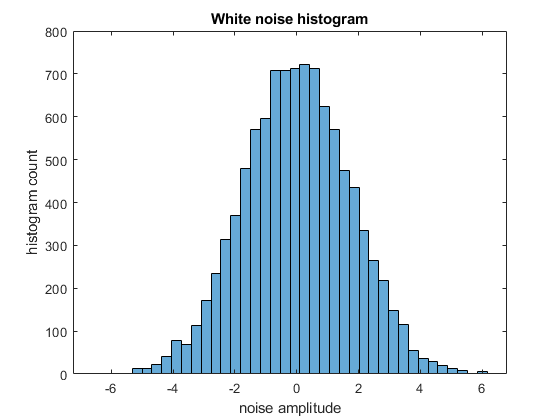


figure 
histogram(noise,40) 
xlabel('noise amplitude') 
ylabel('histogram count') 
title('White noise histogram')

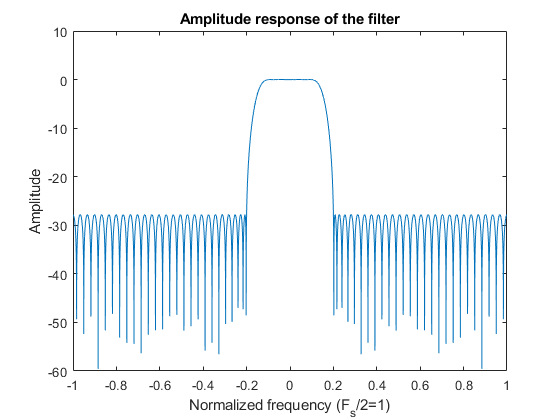


N_filter = 60; %even number 
h = firpm(N_filter,[0 0.1 0.2 1],[1 1 0 0]);

N_freq =  length(noise); 
freq_vec_filter = -1:2/N_freq:(1-2/N_freq); 
%frequency vector values normalized between -1 and 1 
 
figure
plot(freq_vec_filter,10*log10(fftshift(abs(fft(h,N_freq))))) 
xlabel('Normalized frequency (F_s/2=1)') 
ylabel('Amplitude') 
title('Amplitude response of the filter')

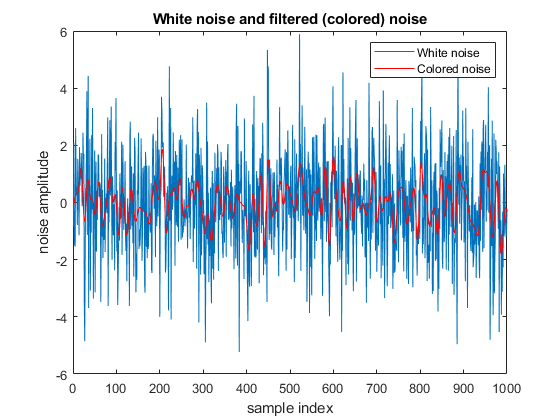


% Filter the noise signal: 
filtered_noise = filter(h,1,noise);

filtered_noise = filtered_noise(N_filter/2+1:end); %remove the delay 
N_samples_plot = 1000; 
figure, plot(noise(1:N_samples_plot)) 
hold on 
plot(filtered_noise(1:N_samples_plot),'r') 
legend('White noise','Colored noise') 
xlabel('sample index') 
ylabel('noise amplitude') 
title('White noise and filtered (colored) noise') 

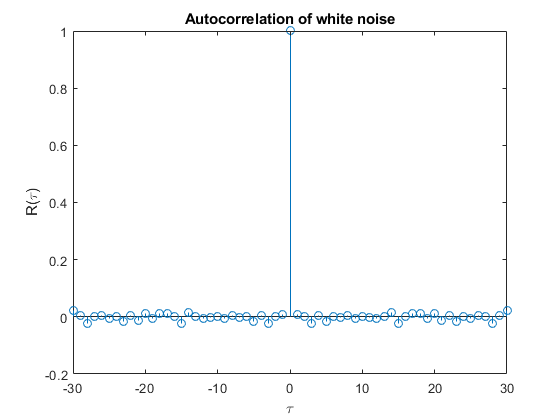


[corr_fun, lags] = xcorr(noise); 
% we normalize the max-value to 1 and use stem-function in order to emphasize 
% the impulse-like nature of the outcome 
figure,stem(lags,corr_fun/max(corr_fun))  
xlabel('\tau') 
% \tau gives the Greek tau-letter (\ works generally for the Greek alphabet) 
ylabel('R(\tau)') 
title('Autocorrelation of white noise') 
xlim([-30 30])

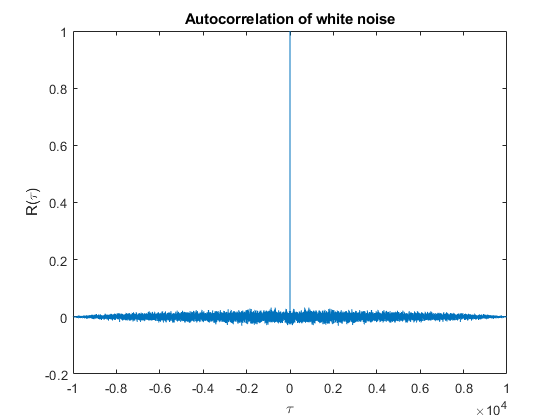



figure,plot(lags,corr_fun/max(corr_fun))
xlabel('\tau')
ylabel('R(\tau)')
title('Autocorrelation of white noise')

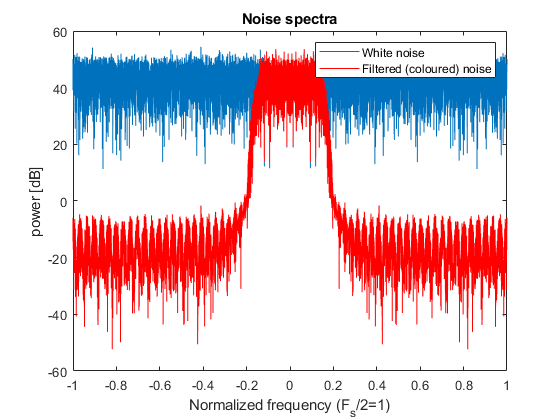


noise_abs_spec = 20*log10(abs(fft(noise(1:length(filtered_noise))))); 
filtered_noise_abs_spec = 20*log10(abs(fft(filtered_noise))); 
 
%Define the frequency vector values (normalized between -1 and 1): 
freq_vec = -1:2/length(noise_abs_spec):1-2/length(noise_abs_spec); 
 
figure 
plot(freq_vec,fftshift(noise_abs_spec)) 
hold on 
plot(freq_vec,fftshift(filtered_noise_abs_spec),'r') 
hold off 
xlabel('Normalized frequency (F_s/2=1)') 
ylabel('power [dB]') 
title('Noise spectra') 
legend('White noise','Filtered (coloured) noise')

### 2.2. Random Walk Model

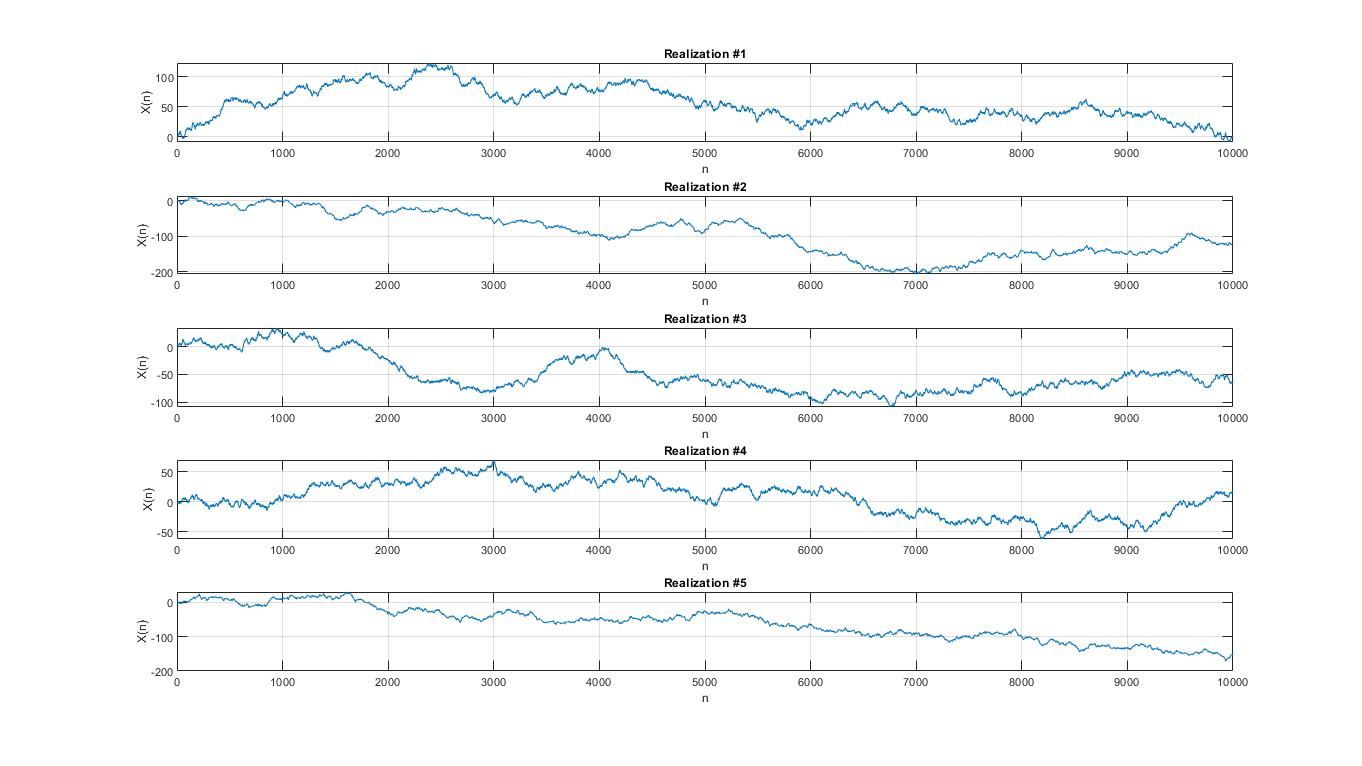

N_samples =10000; %Number of samples for each realization 
N_ensemble = 10000; 
%Number of signal realizations (i.e., the size of ensemble) 
% out of memory in my laptop in N_ensembels > 10000

%Step probability and step size: 
p = 0.5; % P(Wi=s) = p, P(Wi=-s) = 1-p 
s = 1; %step length 
 
n = 1:N_samples; % vector of samples indices 
 
% Generating matrix of randomly generated steps: 
W = rand(N_ensemble,N_samples); 

% (i.e. uniformly distributed random values between 0 and 1) 
 
indices_with_positive_s = W<p; % find out steps going "up" 
 
W(indices_with_positive_s) = s; % Define steps for going "up" 
W(~indices_with_positive_s) = -s; % Define steps for going "down" 
 
 
% The overall "random walk" is achieved by taking the cumulative sum over the 
% steps: 
X = cumsum(W,2);  
% (Notice that now each row describes one random walk realization, so the sum 
% is taken over the 2nd dimension)
figure 
for ind = 1:5 
    subplot(5,1,ind) 
    plot(n,X(ind,:)) 
    xlabel('n') 
    ylabel('X(n)') 
    grid on 
    title(['Realization #' num2str(ind)]) 
    %num2str converts a numerical value into a character value 
end 
 
% Here is a handy way to get a full screen figure 
% (otherwise the figure might be to unclear): 
set(gcf,'units','normalized','outerposition',[0 0 1 1])

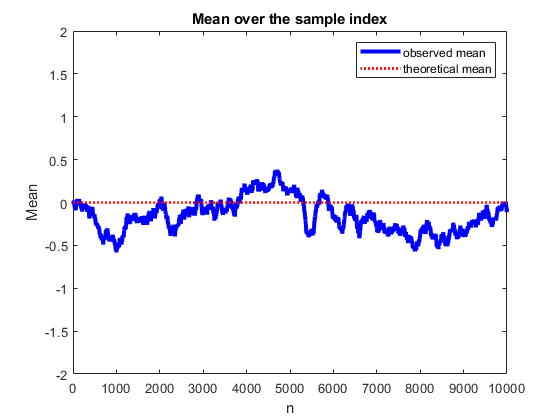


mean_theory = n*s*(2*p-1); % Theoretical mean 
var_theory = n*(2*s)^2*p*(1-p); % Theoretical variance 
 
mean_observed = mean(X); % Empirical mean (i.e., what we observe) 
var_observed = var(X); % Empirical variance (i.e., what we observe) 
 
figure 
plot(n,mean_observed,'b','LineWidth',3) 
hold on 
plot(n,mean_theory,'r:','LineWidth',2) 
hold off 
legend('observed mean','theoretical mean') 
ylim([-2 2]) % set the axis limits in y-direction only 
xlabel('n') 
ylabel('Mean') 
title('Mean over the sample index') 

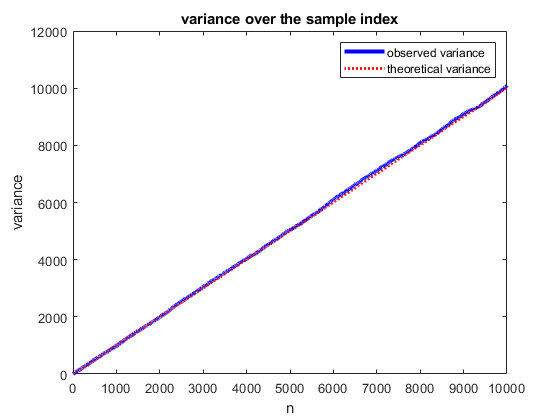


% and the same for the variance…
figure 
plot(n,var_observed,'b','LineWidth',3) 
hold on 
plot(n,var_theory,'r:','LineWidth',2) 
hold off 
legend('observed variance','theoretical variance') 
xlabel('n') 
ylabel('variance') 
title('variance over the sample index') 